# 16 Multitapers

The multitaper approach is an extension of the short-time FFT method that is designed to increase the signal-to-noise ratio of the frequency representation by applying several tapers that have slightly different temporal (and thus spectral) characteristics.

## 16.1 How the Multitaper Method Works

The multitaper method begins similarly to the short-time FFT: 

- From the entire trial period, one time segment is extracted.

- Next, the data from that time segment are multiplied by a series of tapers, resulting in several tapered time series.

- Next, the FFT of each tapered time series is taken.

- The resulting spectra are averaged together.

This procedure can be contrasted with the short-time FFT approach:

- The short-time FFT approach and the multitaper method differ only in that the multitaper approach uses multiple tapers.

- The power spectrum from the multitaper is smoother than the power spectrum obtained from the short-time FFT.

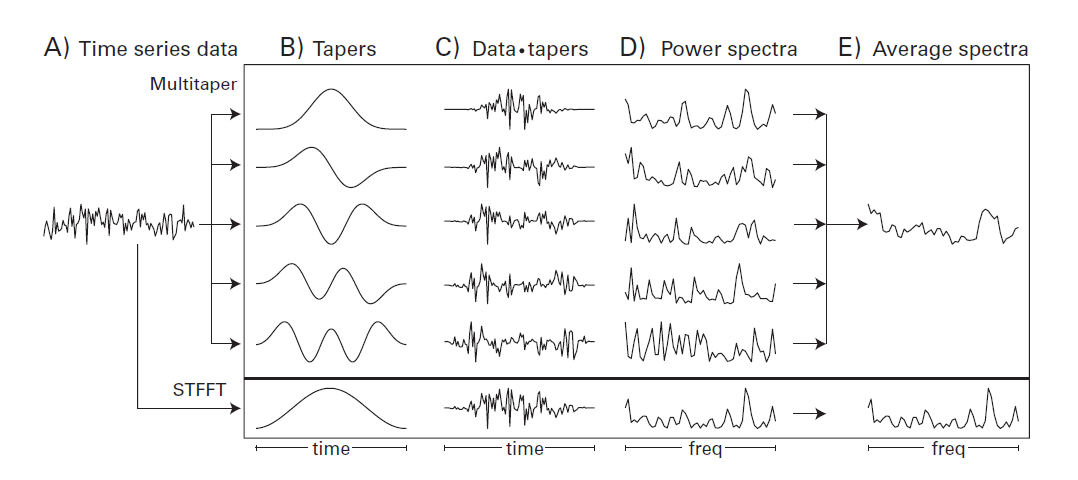

**Figure 16.1**

*Overview of the multitaper method and comparison with the short-time FFT approach.*

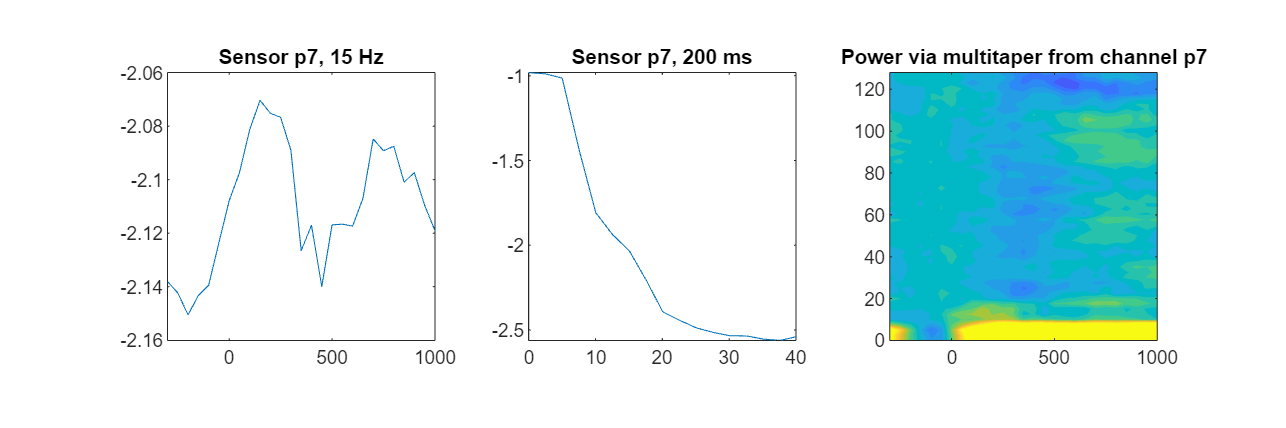

load sampleEEGdata

channel2plot    = 'p7';
frequency2plot  = 15;
timepoint2plot  = 200;

nw_product      = 3;
times2save      = -300:50:1000;
baseline_range  = [-200 -00];
timewin         = 400;

times2saveidx = dsearchn(EEG.times',times2save'); 
timewinidx    = round(timewin/(1000/EEG.srate));

baseidx = zeros(size(baseline_range));
[~,baseidx(1)] = min(abs(times2save-baseline_range(1)));
[~,baseidx(2)] = min(abs(times2save-baseline_range(2)));

tapers = dpss(timewinidx,nw_product);
frex = linspace(0,EEG.srate/2,floor(timewinidx/2)+1);
chanidx = strcmpi(channel2plot,{EEG.chanlocs.labels});

multitaper_tf = zeros(floor(timewinidx/2)+1,length(times2save));

for ti=1:length(times2saveidx)
    
    taperpow = zeros(floor(timewinidx/2)+1,1);

    for tapi = 1:size(tapers,2)-1
        
        data      = bsxfun(@times,squeeze(EEG.data(chanidx,times2saveidx(ti)-floor(timewinidx/2)+1:times2saveidx(ti)+ceil(timewinidx/2),:)),tapers(:,tapi));
        pow       = fft(data,timewinidx)/timewinidx;
        pow       = pow(1:floor(timewinidx/2)+1,:);
        taperpow  = taperpow + mean(pow.*conj(pow),2);
    end
    
    multitaper_tf(:,ti) = taperpow/tapi;
end

db_multitaper_tf = 10*log10( multitaper_tf ./ repmat(mean(multitaper_tf(:,baseidx(1):baseidx(2)),2),1,length(times2save)) );


figure(Position=[100,100,1500,500])

subplot(131)
[~,freq2plotidx]=min(abs(frex-frequency2plot));
plot(times2save,mean(log10(multitaper_tf(freq2plotidx-2:freq2plotidx+2,:)),1))
title([ 'Sensor ' channel2plot ', ' num2str(frequency2plot) ' Hz' ])
axis square
set(gca,'xlim',[times2save(1) times2save(end)])

subplot(132)
[junk,time2plotidx]=min(abs(times2save-timepoint2plot));
plot(frex,log10(multitaper_tf(:,time2plotidx)))
title([ 'Sensor ' channel2plot ', ' num2str(timepoint2plot) ' ms' ])
axis square
set(gca,'xlim',[frex(1) 40])

subplot(133)
contourf(times2save,frex,db_multitaper_tf,40,'linecolor','none')
set(gca,'clim',[-2 2])
title([ 'Power via multitaper from channel ' channel2plot ])
axis square

**Figure 16.2**

*Same data as shown in figure 15.2, but the results were obtained via the multitaper method instead of the short-time FFT method.*

The multitaper method can be used to extract both power and phase information. Because the phase value per frequency may change with each taper, the phase values obtained from the multitaper approach reflect an average phase from the tapered data time series. As with the short-time FFT method, the phase values here refer to the phase of the sine wave in that time segment at each frequency rather than the ongoing phase-angle time series. Also as with the short-time FFT, phase values from the multitaper method can be used for many phase-based analyses.

## 16.2 The Tapers

The tapers used for the multitaper method are called discrete prolate spheroidal sequences and can be obtained via the Matlab function `dpss` (in the signal processing toolbox):

They are also often called Slepian tapers. Slepian tapers are orthogonal to each other, and they have slightly different frequency characteristics, thus focusing the spectra of the resulting tapered time series on different parts of the spectrum.

The multitaper method introduces some smoothing on the frequency axis. The amount of smoothing depends on the number of tapers. Frequency smoothing may be beneficial for:

- Higher-frequency activity, in which the spectrum tends to be broader than at lower frequencies

- Cross-subjects group-level averaging

The multitaper method also introduces temporal smoothing, particularly more temporal smoothing when compared to wavelet convolution or the filter-Hilbert method because of the multiple tapers with different temporal foci within each time segment. Temporal smoothing might be beneficial in: 

- The identification of high-frequency activity

- Cross-subjects group-level averaging

The number of tapers that the Matlab function dpss will return is computed based on the product of the desired segment length (in sample points) and the frequency half-bandwidth (as a fraction of the sampling rate) is the second input argument to the Matlab dpss function:

### 
$$\textrm{NW}=N\times \frac{W}{F_s }$$


- $N$ is the number of samples in one analysis window

- $F_s$ is the sampling rate in Hz

- $W$ is the desired half-bandwidth

The number of tapers is twice this product, rounded to the nearest integer:

### 
$$K\approx 2\textrm{NW}$$


The product of the segment length and the desired spectral smoothing can be: 

- Kept at a constant 

- Allowed to vary as a function of frequency band 

This latter option improves the time-frequency trade-off between temporal and frequency precision as a function of frequency.

The last taper of the sequence generally has a relatively poor spectral representation and thus can be omitted from the analysis. This can be seen by plotting the second output of dpss, which is related to the energy in the specified band and ideally should be close to 1.0.

There is a trade-off between smoothness and accuracy, such that smoother results (thus, more tapers) decrease the accuracy of the frequency characteristics of the data. The results should be smoothed enough to increase the signal-to-noise ratio, but not at the expense of losing sensitivity to detect time-frequency features. The same smoothing criteria should be applied to all electrodes and conditions to minimize the possibility that a bias in frequency estimation will affect the results.

As with the short-time FFT method, the multitaper method will return as many frequency bins between zero and the Nyquist frequency as there are time points in each segment. Thus, you have the option of selecting requested frequencies based on a single frequency bin or the average of neighboring frequency bins. However, because the multitaper method already involves spectral smoothing and averaging, it may not be necessary to further average over frequency bins when extracting power from the multitaper-averaged spectra.

## 16.3 When You Should and Should Not Use Multitapers

There are four situations in which the multitaper approach may be beneficial to your results: 

- Noisy data

- Single-trial analyses

- High-frequency power, particularly above around 60 Hz

- Cross-subjects group-level averaging

Several EEG analysis toolboxes will perform a multitaper-based timefrequency decomposition. However, the Matlab toolbox fieldtrip has the most active development of this method.

There are two situations in which the multitaper approach might not be the preferred method:

- Frequencies below around 30 Hz

- Precise timing of high-frequency activity is required

## 16.4 The Multitaper Framework and Advanced Topics

Multitapers should be seen as a general framework for a set of possible analysis approaches. The material presented in this chapter provides a basic introduction to the multitaper framework. More sophisticated applications of multitaper include: for example:

- varying the lengths of the time segments, as a function of the center frequencies.

- varying the number of tapers, as a function of the center frequencies.

- varying the center frequency of the spectral representation of the tapers, as a function of the center frequencies. 

Further, there are more advanced methods for estimating the appropriate frequency smoothing and number of tapers to use, adaptively weighting the contribution of different frequency bands to optimize averaging, and performing statistical evaluation of whether spectral peaks are statistically significant.

## 16.5 Describing This Analysis in Your Methods Section

There are several important details about the multitaper method that should be mentioned in the Methods section, including: 

- The length of the time segment

- The number of frequencies that were extracted

- The number of Slepian tapers

- The resulting smoothing

If the analysis was done in a Matlab toolbox such as fieldtrip, state whether the default parameters were used and list any nondefault parameters otherwise.